# Gabriel Colangelo

clear
close all
clc

## Problem 1a) - Why is the Orbit Hyperbolic?

% Constants
R_moon  = 1738.2;           % [km]
mu_moon = 4902.8005821478;  % [km^3/s^2]

% Position vector - perifocal coordiantes
r       = [0;-9*R_moon;0];  % [phat direction]

% Velocity squared
v2      = 41*mu_moon/(144*R_moon);

% Calculate energy
energy  = v2/2 - mu_moon/norm(r);
fprintf('The speicific energy is %.3f km^2/s^2', energy)

The speicific energy is 0.088 km^2/s^2


$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r} \\ 
\epsilon =  0.0881 \ [km^2/s^2]$$


**The orbit is known to be hyperbolic because the specific energy is greater than 0, which is a property of only hyperbolic orbits**.

## Problem 1b)


$$\underline{Find}: r_p, v_p, e, b, d_{aim}, p,h,\delta, v_{\infty}, \epsilon, \theta^*_{\infty}, \text{and} \  r,v,\gamma \ \text{for} \ \theta^*  = \pm 120$$


% Determine semi major axis
a_abs   = mu_moon/(2*energy);

% Semi-latus rectum - current position vector aligned with p direction
p       = norm(r);
fprintf('The semi-latus rectum is %.3f moon radii',p/R_moon)

The semi-latus rectum is 9.000 moon radii

**The current position vector is aligned with **$\hat{p}$**, the magnitude of the position vector is thus the semi-latus rectum**

% Calculate eccentricity
e       = sqrt(p/a_abs + 1);
fprintf('The eccentricity is %.3f ', e)

The eccentricity is 1.250 


$$|a|= \frac{\mu}{2\epsilon} \\
p = |a|(e^2 - 1) \\
e = \sqrt{p/|a| +1} \\
e = 1.25
$$


% Calculate distance to periapsis
rp      = a_abs*(e - 1);
fprintf('The distance to periapsis is %.2f Moon Radii',rp/R_moon)

The distance to periapsis is 4.00 Moon Radii


$$r_p = |a|(e - 1)
r_p = 4 \ [R_{moon}]$$


% Calculate velocity at periapsis
vp      = sqrt(2*mu_moon/rp + mu_moon/a_abs);
fprintf('The velocity at periapsis is %.3f km/s',vp)

The velocity at periapsis is 1.260 km/s


$$\epsilon = \frac{\mu}{2|a|} = \frac{v^2}{2} - \frac{\mu}{r} \\
v_p = \sqrt{\frac{2\mu}{r_p} + \frac{\mu}{|a|}} = 1.26\ [km/s]$$


% Calculate aiming radius
b       = a_abs*sqrt(e^2 - 1);
fprintf('The aiming radius is %.3f moon radii',b/R_moon)

The aiming radius is 12.000 moon radii


$$b = |a|\sqrt{e^2 -1}
b  = 12 \ [R_{moon}]$$


% Calculate distance from aim point to center of hyperbola
daim    = sqrt((a_abs*e)^2 - b^2);
fprintf('The distance from aim point to center of hyperbola is %.3f moon radii',daim/R_moon);

The distance from aim point to center of hyperbola is 16.000 moon radii


$$b^2 + d_{aim}^2 = (|a|e)^2 \\
d_{aim} = \sqrt{ (|a|e)^2 -  b^2} \\
d_{aim} = 16 \ [R_{moon}]$$


% Calculate specific angular momentum
h       = sqrt(mu_moon*p);
fprintf('The specific angular momentum is %.3f km^2/s',h)

The specific angular momentum is 8757.764 km^2/s


$$h = \sqrt{\mu p} \\
h  = 8757.8 \ [km^2/s]$$


% Calculate true anomaly of the asymptote
ta_inf  = acosd(-1/e);
fprintf('The true anomaly of the asymptote is %.3f deg',ta_inf)

The true anomaly of the asymptote is 143.130 deg


$$\cos{\theta^*_\infty} = -1/e \\
\theta^*_\infty = 143.1 \ [deg]$$


% Calculate fly by angle
delta   = 2*asind(1/e);
fprintf('The fly by angle is %.3f deg', delta)

The fly by angle is 106.260 deg


$$\sin{\delta} = 1/e \\
\delta = 143.1 \ [deg]$$


% Calculate excess velocity
v_inf   = sqrt(2*energy);
fprintf('The excess velocity is %.3f km/s',v_inf)

The excess velocity is 0.420 km/s


$$\epsilon = v_\infty^2/2 \\
v_\infty = 0.42 \ [km/s]$$


% Calculate distance for true anomaly of 120
r_120   = p/(1 + e*cosd(120));
fprintf('The orbital radius for a true anomaly of 120 deg is %.3f moon Radii',r_120/R_moon)

The orbital radius for a true anomaly of 120 deg is 24.000 moon Radii


$$r = \frac{p}{1 + e\cos{\theta^*}} \\
r_{\theta^* = 120}  = 24 \ [R_{moon}]$$


% Orbital speed for true anomaly of 120
v_120   = sqrt(2*(energy + mu_moon/r_120));
fprintf('The orbital speed for true anomaly of 120 is %.3f km/s', v_120)

The orbital speed for true anomaly of 120 is 0.641 km/s


$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r}\\ 
v_{\theta^* = 120} = \sqrt{2(\epsilon + \frac{\mu}{r_{\theta^* = 120}})} \\
v_{\theta^* = 120} = 0.64 \ [km/s]$$


% Calculate flight path angle
gamma_120   = acosd(h/(r_120*v_120));
fprintf('The flight path angle for a true anomaly fo 120 deg is %.3f deg', gamma_120)

The flight path angle for a true anomaly fo 120 deg is 70.893 deg


$$\cos{\gamma} = \frac{h}{rv} \\
\gamma_{\theta^* = 120}  =  70.9 \ [deg]$$


% Calculate distance for true anomaly of -120
r_n120   = p/(1 + e*cosd(-120));
fprintf('The orbital radius for a true anomaly of -120 deg is %.3f moon Radii',r_n120/R_moon)

The orbital radius for a true anomaly of -120 deg is 24.000 moon Radii


$$r = \frac{p}{1 + e\cos{\theta^*}} \\
r_{\theta^* = -120}  = 24 \ [R_{moon}]$$


% Orbital speed for true anomaly of -120
v_n120   = sqrt(2*(energy + mu_moon/r_n120));
fprintf('The orbital speed for true anomaly of -120 is %.3f km/s', v_n120)

The orbital speed for true anomaly of -120 is 0.641 km/s


$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r}\\ 
v_{\theta^* = -120} = \sqrt{2(\epsilon + \frac{\mu}{r__{\theta^* = 120}})} \\
v_{\theta^* = -120}= 0.64 \ [km/s]$$


% Calculate flight path angle - nagtive sign due to sign of true anomaly
gamma_n120   = -acosd(h/(r_120*v_120));
fprintf('The flight path angle for a true anomaly fo -120 deg is %.3f deg', gamma_n120)

The flight path angle for a true anomaly fo -120 deg is -70.893 deg


$$\cos{\gamma} = \frac{h}{rv} \\
\gamma_{\theta^* = -120}  =  -70.9 \ [deg]$$


## Problem 1c) Plot Orbit

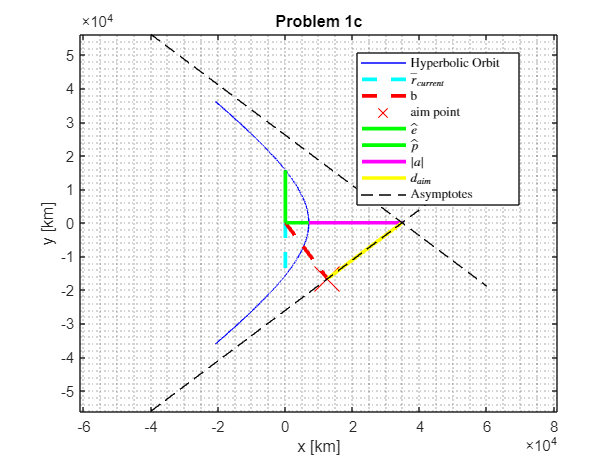

% True Anomaly Vector
ta_vec      = -120:.01:120;

% Initialize Perifocal position vector
r_P         = zeros(2,length(ta_vec)); 

for i = 1:length(ta_vec)

    % Distance to probe from moon
    r_mag     =  p/(1 + e*cosd(ta_vec(i)));

    % Position Vector in Perifocal Frame - Centered at Moon 
    r_P(:,i)  = [r_mag*cosd(ta_vec(i));r_mag*sind(ta_vec(i))]; 
end

% Slope of line
slope       = tand(ta_inf - delta);

% Create asymptote
asym        = slope*((-40000:100:60000) - a_abs*e);

figure
plot(r_P(1,:),r_P(2,:),'-b')
hold on
plot([0, r(1)], [0, r(2)],'Color','cyan','Linestyle','--','LineWidth',2.5)
plot([0, b*cosd(-delta/2)], [0, b*sind(-delta/2)],'Color','red','Linestyle','--','LineWidth',2.5)
plot(b*cosd(-delta/2),b*sind(-delta/2),'rx','MarkerSize',24)
plot([0,rp], [0, 0],'Color','green','Linestyle','-','LineWidth',2.5)
plot([0, 0], [0, p],'Color','green','Linestyle','-','LineWidth',2.5)
plot([rp rp+a_abs], [0 0],'Color','magenta','Linestyle','-','LineWidth',2.5)
plot([b*cosd(-delta/2), a_abs*e],[b*sind(-delta/2),0],'Color','yellow','Linestyle','-','LineWidth',2.5)
plot((-40000:100:60000), -asym,'--k')
plot((-40000:100:60000), asym,'--k')
title('Problem 1c')
axis equal
grid minor
hold on
xlabel('x [km]')
ylabel('y [km]')
legend('Hyperbolic Orbit','$\bar{r}_{current}$','b','aim point',...
       '$\hat{e}$','$\hat{p}$','$\left| a \right|$','$d_{aim}$','Asymptotes',...
       'Location', 'best','Interpreter','latex')
hold off

## Problem 1e)


$$\underline{Find}:  \bar{r},\bar{v} \ \text{for} \ \theta^*  = \pm 120$$
    

% Orbital elements
i           = 45;   % Inclination [deg]
w           = 90;   % Argument of periapsis [deg]
RAAN        = 60;   % Right ascension of ascending node [deg]

% Velocity vectors for true anomaly +/- 120 in orbit frame
v_R_120     = [v_120*sind(gamma_120);v_120*cosd(gamma_120);0];
v_R_n120    = [v_n120*sind(gamma_n120);v_n120*cosd(gamma_n120);0];

% Function handles
C           = @(x) cosd(x);
S           = @(x) sind(x);

% Define theta for true anomaly of 120 deg and -120
theta_120   = w + 120;
theta_n120  = w - 120;

% Direction cosine matrix rotating from orbit frame to lunar equatorial inertial frame
I_DCM_R_120 = [C(RAAN)*C(theta_120) - S(RAAN)*C(i)*S(theta_120), -C(RAAN)*S(theta_120) - ...
              S(RAAN)*C(i)*C(theta_120) S(RAAN)*S(i); S(RAAN)*C(theta_120) + ...
              C(RAAN)*C(i)*S(theta_120), -S(RAAN)*S(theta_120) + C(theta_120)*C(i)*C(RAAN),...
              -C(RAAN)*S(i);S(i)*S(theta_120), S(i)*C(theta_120), C(i)];

I_DCM_R_n120= [C(RAAN)*C(theta_n120) - S(RAAN)*C(i)*S(theta_n120), -C(RAAN)*S(theta_n120) - ...
              S(RAAN)*C(i)*C(theta_n120) S(RAAN)*S(i); S(RAAN)*C(theta_n120) + ...
              C(RAAN)*C(i)*S(theta_n120), -S(RAAN)*S(theta_n120) + C(theta_n120)*C(i)*C(RAAN),...
              -C(RAAN)*S(i);S(i)*S(theta_n120), S(i)*C(theta_n120), C(i)];

% Rotate position and velocity vectors from rotating orbit frame to lunar equatorial inertial frame
r_I_120     = I_DCM_R_120*[r_120;0;0]/R_moon;
v_I_120     = I_DCM_R_120*v_R_120;

r_I_n120    = I_DCM_R_n120*[r_n120;0;0]/R_moon;
v_I_n120    = I_DCM_R_n120*v_R_n120;


$$[IR] =  \pmatrix{C_{\Omega} C_{\theta} - S_{\Omega} C_i S_{\theta}& -C_{\Omega} S_{\theta} - S_{\Omega} C_i C_{\theta}&
              S_{\Omega} S_i\cr S_{\Omega} C_{\theta} + C_{\Omega} C_i S_{\theta}& -S_{\Omega} S_{\theta} + C_{\theta} C_i C_{\Omega}&
              -C_{\Omega} S_i \cr S_i S_{\theta}& S_i C_{\theta}& C_i}  \\
[r]^I = [IR] [r]^R \\
[v]^I = [IR] [v]^R \\ 
\\

\bar{r}_{\theta^* = 120} = -3.0438\ \hat{x} - 22.2426 \ \hat{y} - 8.4853\ \hat{z}\ [R_{moon}] \\
\bar{v}_{\theta^* = 120} =  0.0870\ \hat{x} - 0.5350\ \hat{y} \  - 0.3428 \ \hat{z} \ [km/s] \\
\\
\bar{r}_{\theta^* = -120} = 17.7408\ \hat{x} + 13.7574\ \hat{y} - 8.4853\ \hat{z}\ [R_{moon}] \\
\bar{v}_{\theta^* = -120} = -0.5068\ \hat{x} - 0.1922\ \hat{y} \  - 0.3428 \ \hat{z} \ [km/s]$$
